Create a time vector from 0 to 63 seconds

% Thompson emory section 5.4 spectral analysis
N = 64;
dt = 1;  %sample period
t = (0:N-1)'*dt;

## 1) Form a cosine time series with amplitude = 3 and period = 16 sec.  Add a mean offset of 1.  Compute and plot the Fourier coefficients

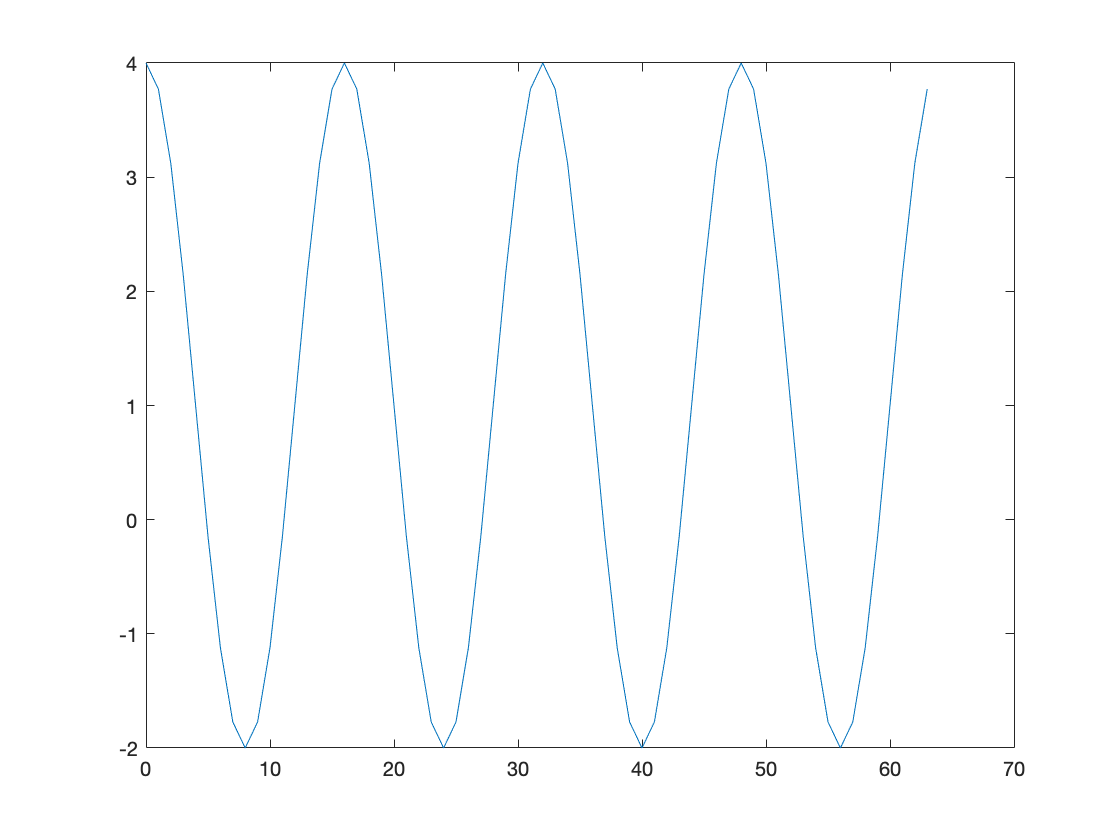

x = 3*cos(2*pi*t/16)+1; % add mean term of 1
plot(t,x)

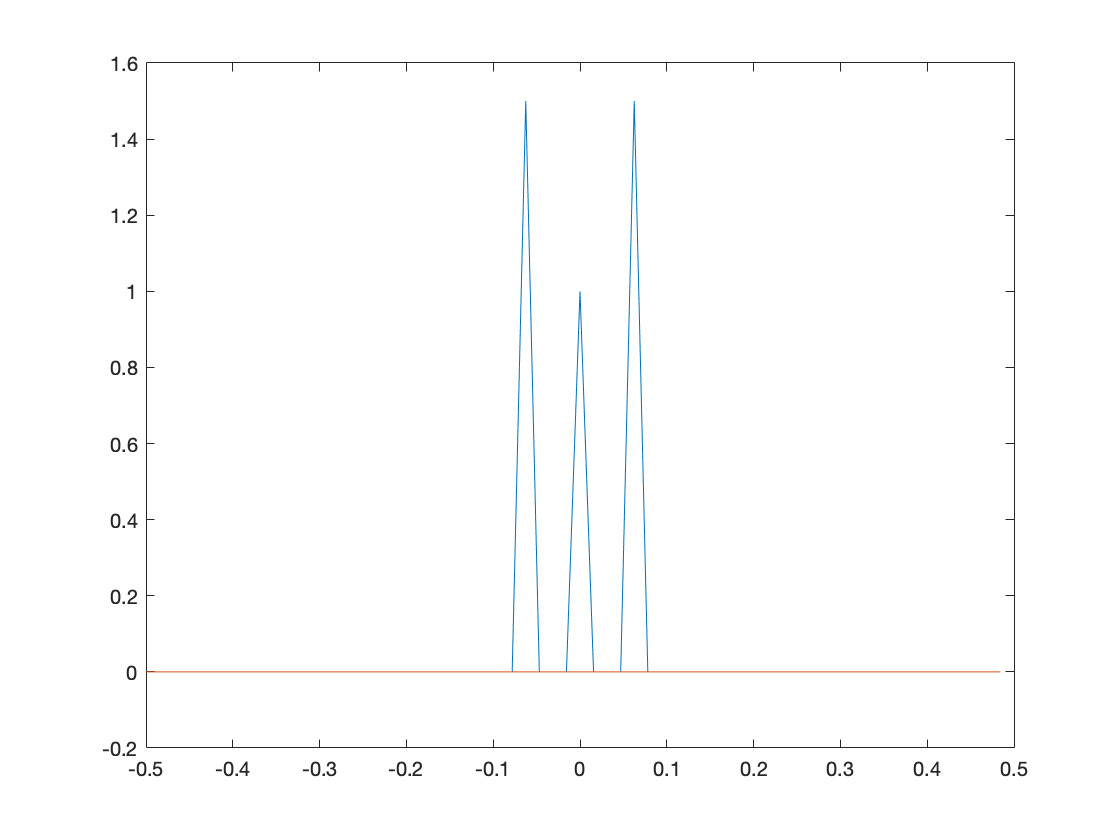

X = fft(x);
X = fftshift(X); % shift neg freq to positive
fN = 1/(2*dt); % nyquist freq (highest freq)
df = 1/(N*dt); % resolution freq
f = (-fN:df:fN)'; % neg nyquist : res freq : pos nyquist
f = f(1:N); % cut off 
plot(f,real(X)/N,f,imag(X)/N)

red is negative part 

middle is mean term

two sides are the mean + 1/16 ???

## 2) Repeat 1) using a sine instead of a cosine

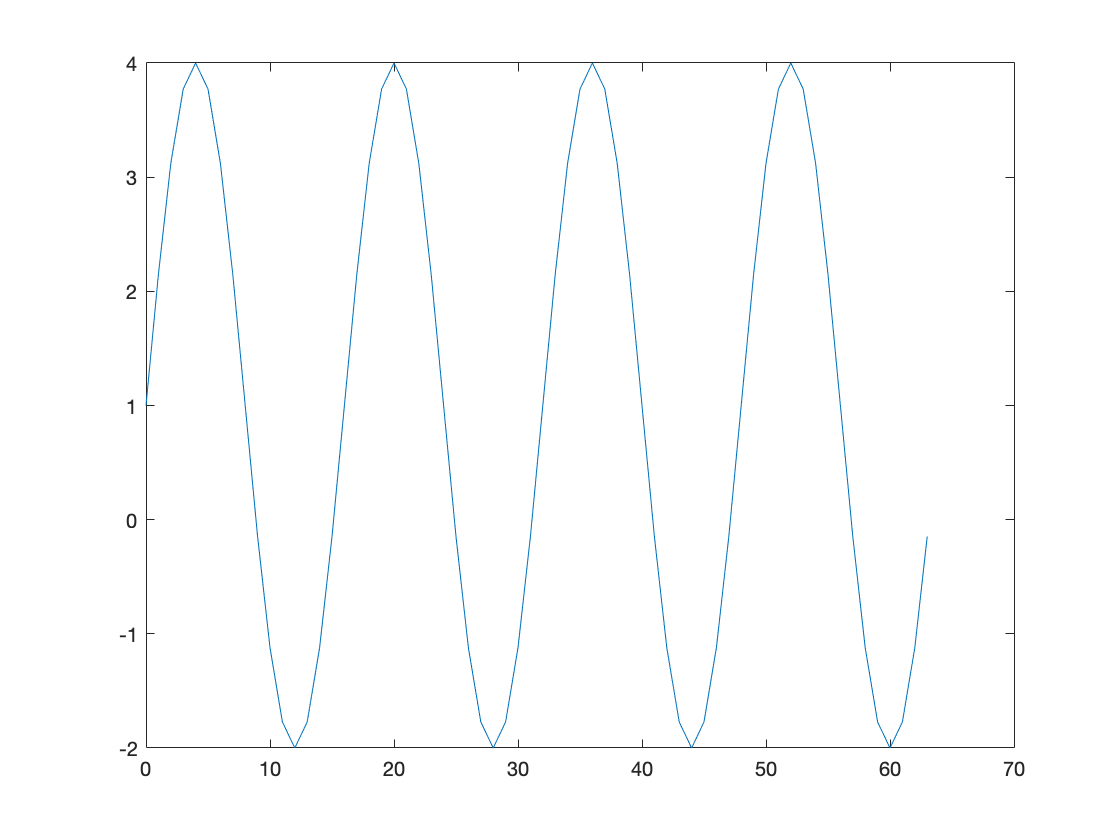

x1 = 3*sin(2*pi*t/16)+1;
clf
plot(t,x1)

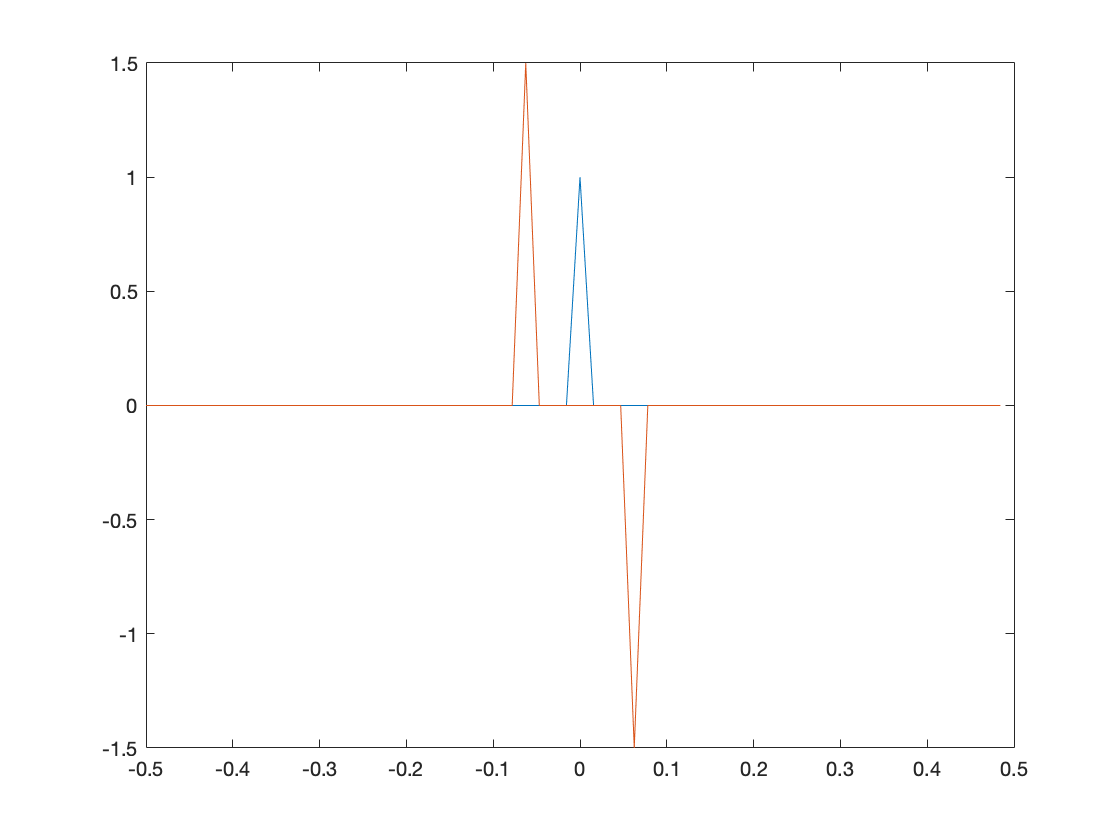

X1 = fft(x1); % get amplitudes
X1 = fftshift(X1);
fN = 1/(2*dt); % nyquist freq (highest freq)
df = 1/(N*dt);
f = (-fN:df:fN)'; % neg nyquist : res freq : pos nyquist
f = f(1:N); % cut off 
plot(f,real(X1)/N,f,imag(X1)/N)

## 3) Repeat 1) adding a sine with amplitude = -1 and period = 8 sec

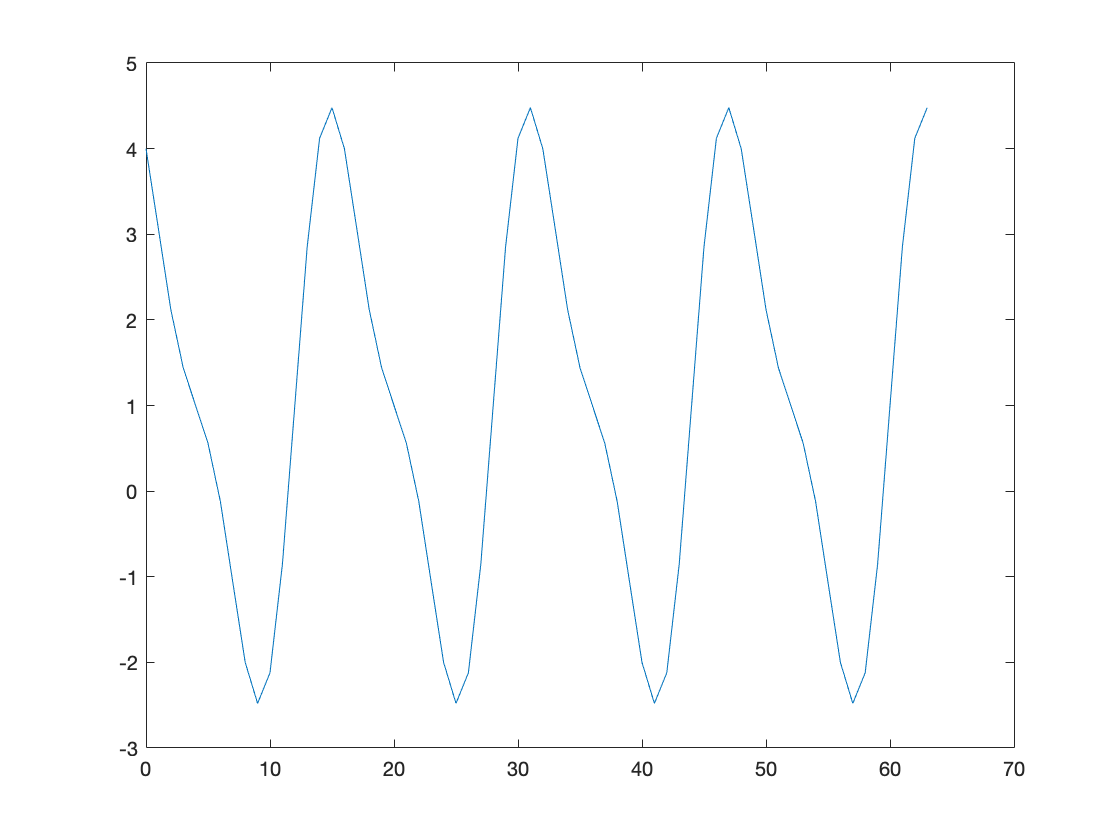

x2 = 3*cos(2*pi*t/16)+1 + -1*sin(2*pi*t/8);
plot(t,x2)

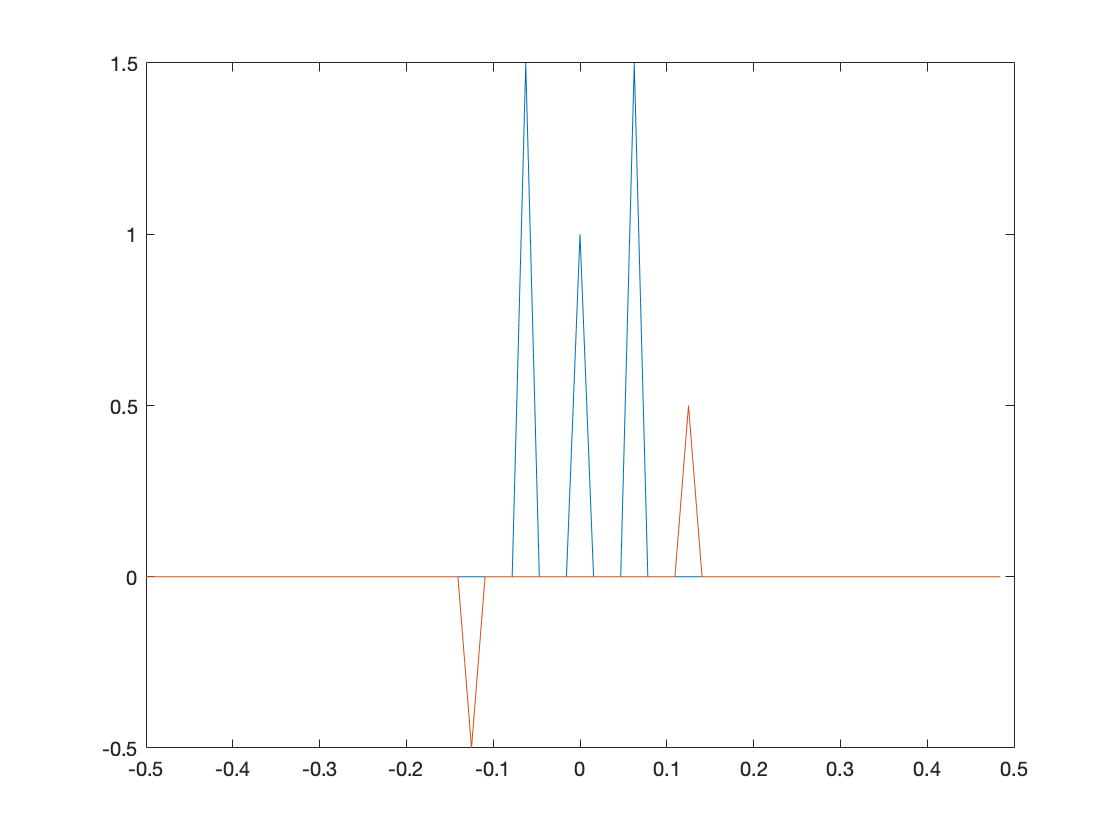

X2 = fft(x2); % get amplitudes
X2 = fftshift(X2);
fN = 1/(2*dt); % nyquist freq (highest freq)
df = 1/(N*dt);
f = (-fN:df:fN)'; % neg nyquist : res freq : pos nyquist
f = f(1:N); % cut off 
plot(f,real(X2)/N,f,imag(X2)/N)

## 4) Repeat 1) adding a sine with amplitude = 2 and period = 16 sec

x3 = 3*cos(2*pi*t/16)+1 + 2*sin(2*pi*t/15);
plot(t,x)

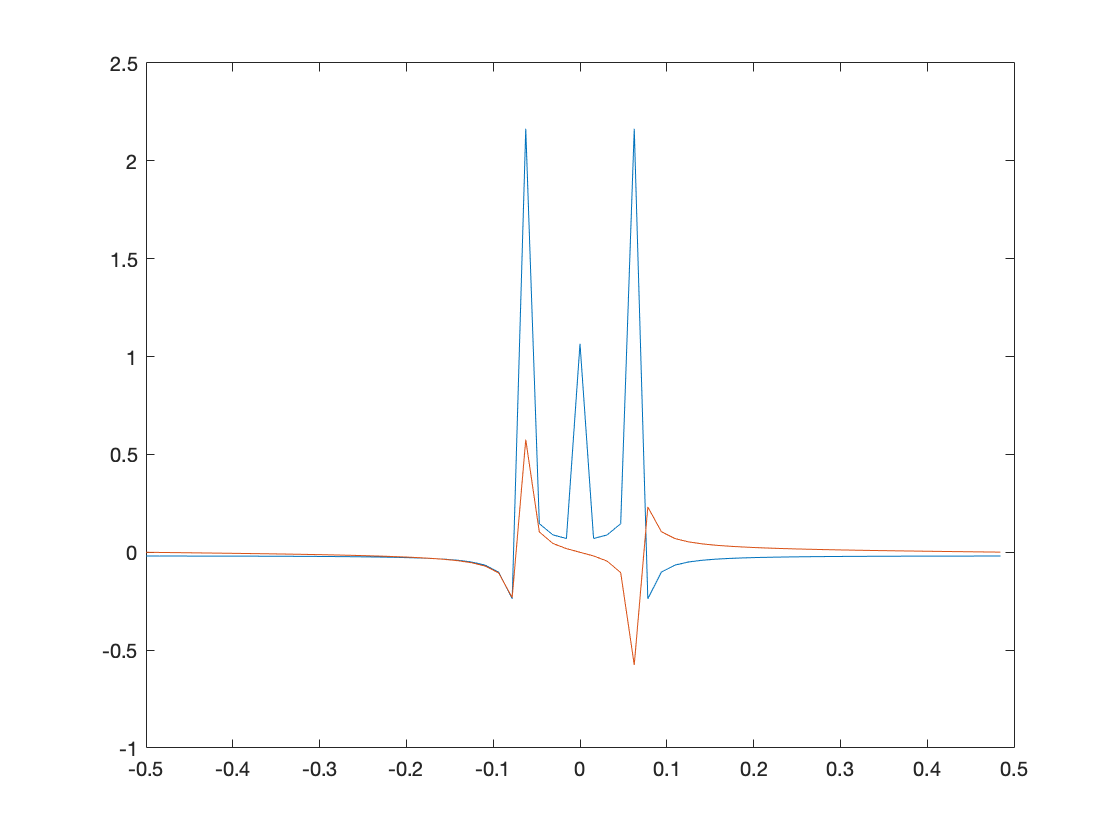

X3 = fft(x3); % get amplitudes
X3 = fftshift(X3);
fN = 1/(2*dt); % nyquist freq (highest freq)
df = 1/(N*dt);
f = (-fN:df:fN)'; % neg nyquist : res freq : pos nyquist
f = f(1:N); % cut off 
plot(f,real(X3)/N,f,imag(X3)/N)

## 5) Form a time series of zeros with a single spike of A = 1 at t = 32.  Compute and plot the Fourier coefficients.  Plot the abs(X)/N vs f.

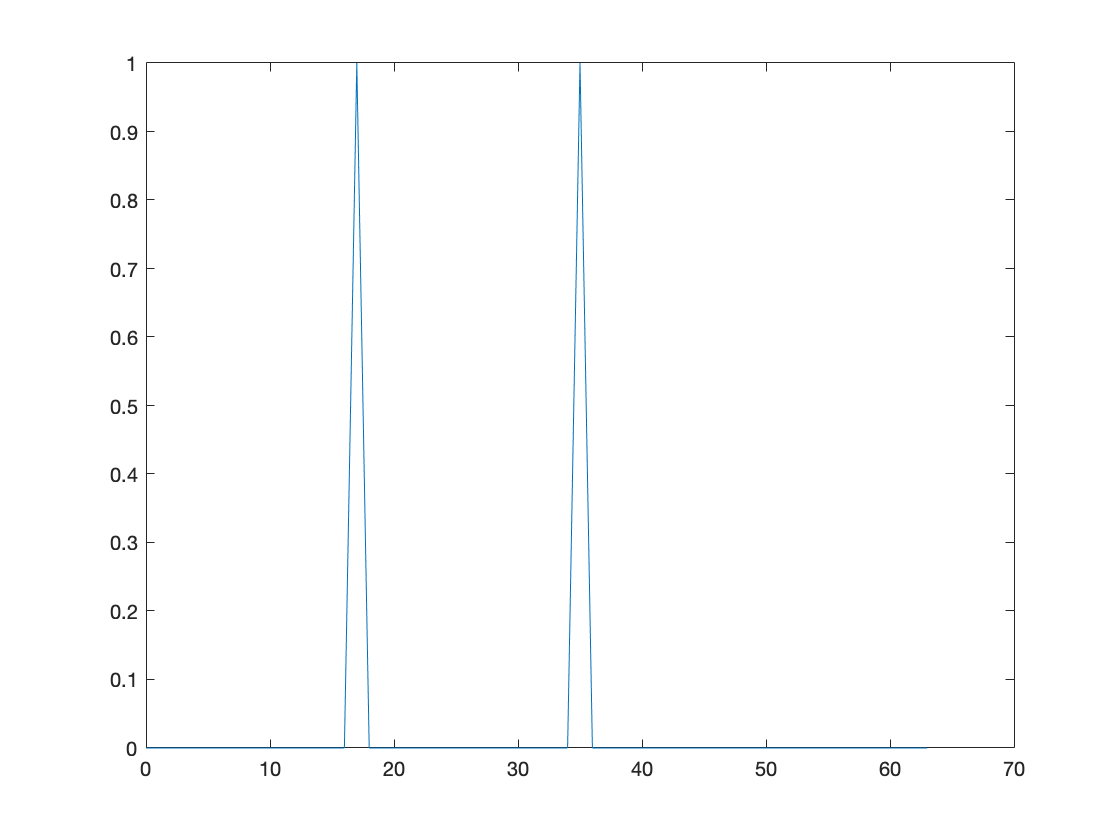

x4 = zeros(64,1);
x4(18,1) = 1;
x4(36,1) = 1;
plot(t,x4)

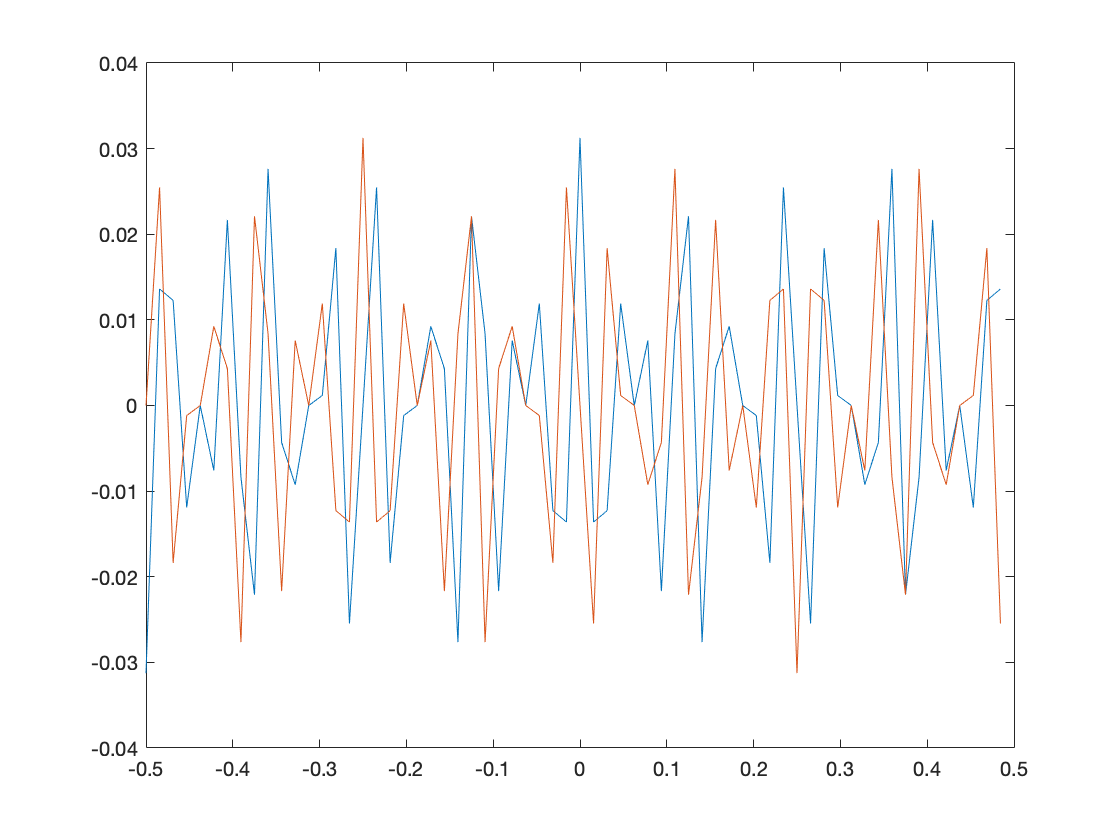

plot(f,real(X4)/N,f,imag(X4)/N)

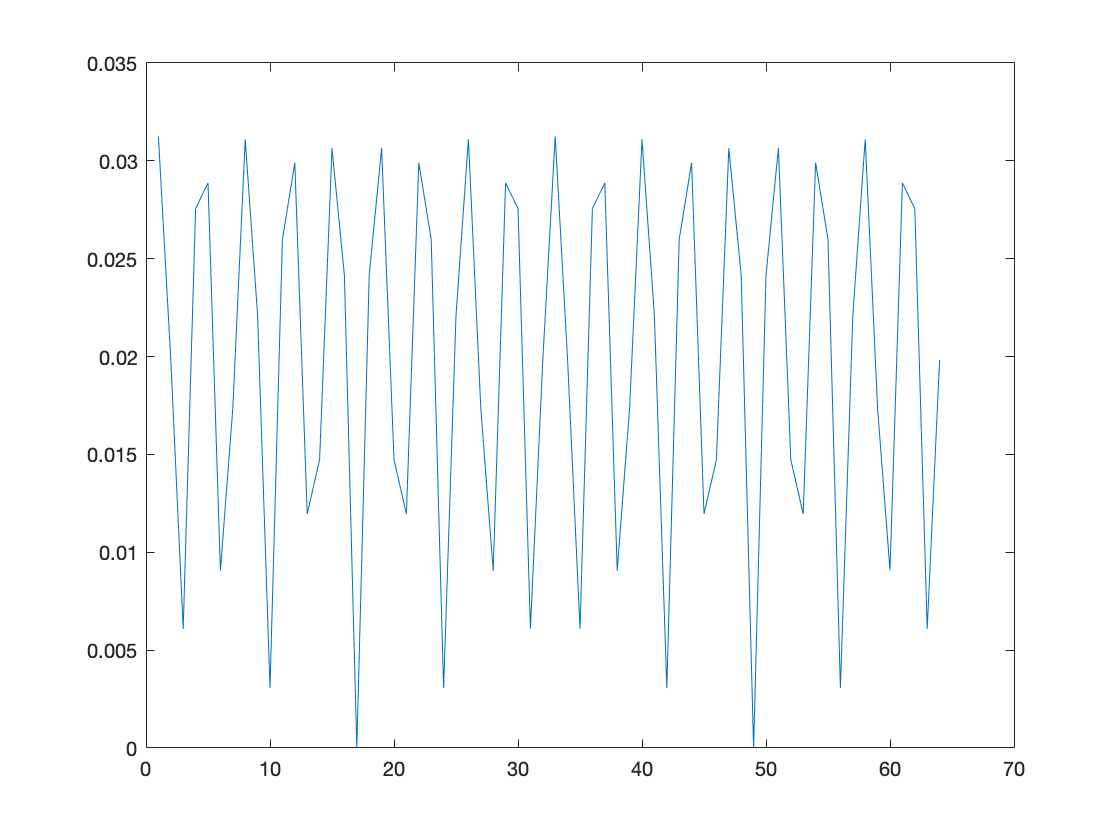

X4 = fft(x4);
X4 = fftshift(X4);
plot(abs(X4)/N) % fourier transform of delta function = constant

## 6) Form a random time series using rand.  Compute and plot the Fourier coefficients.  Plot the abs(X)/N vs f.

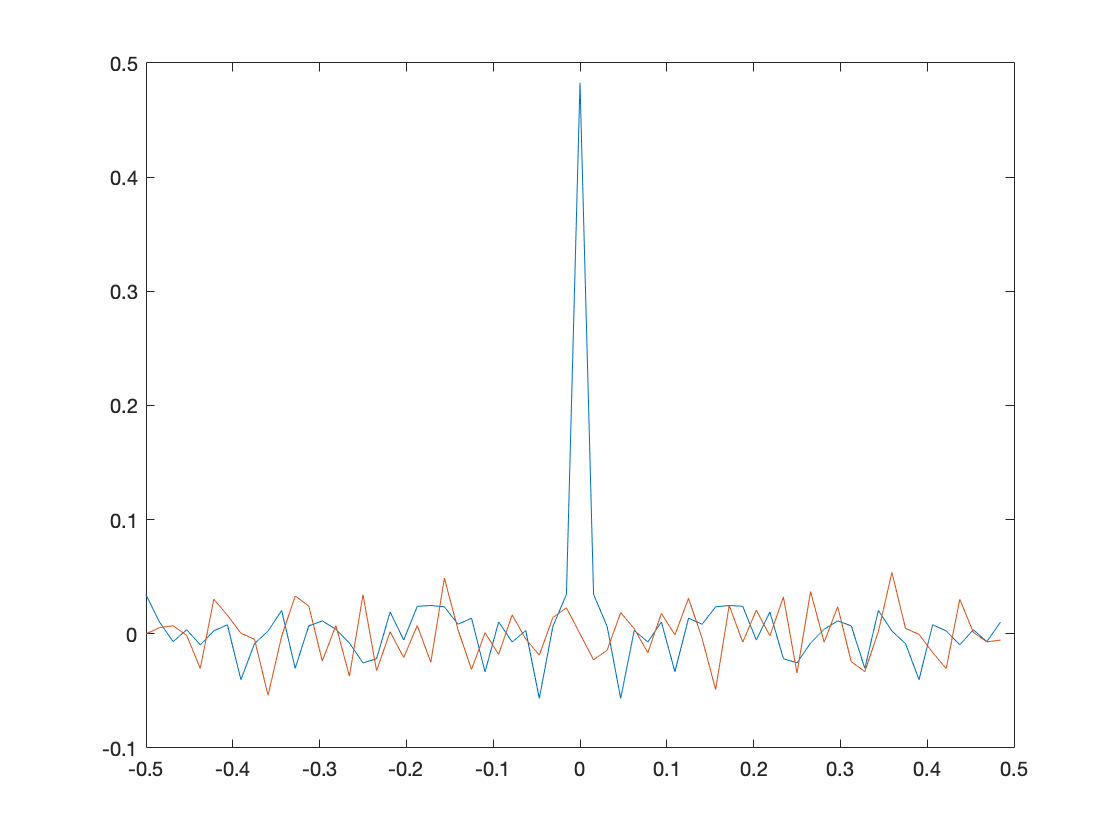

x5 = rand(64,1);
X5=fft(x5);
X5 = fftshift(X5);
plot(f,real(X5)/N,f,imag(X5)/N)

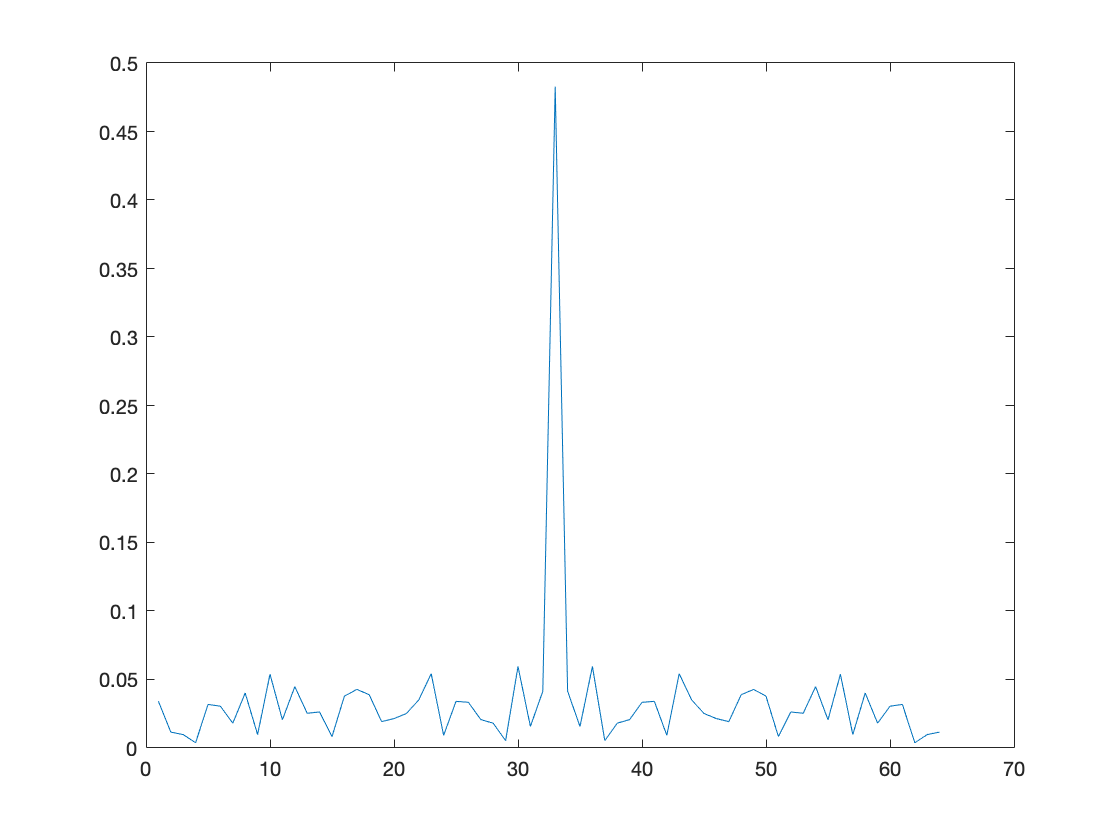

% why do we get a spike at zero?
plot(abs(X5)/N)